# Detection methods

%% Import the model for injection
% one model.
 LCmodel = [1.0,
 1.0,
 1.0,
 1.0,
 1.0,
 1.0,
 1.0,
 0.9934857899250215,
 0.8202584070645508,
 0.5261102433881734,
 0.5261102433881734,
 0.8202584070645476,
 0.9934857899250206,
 1.0,
 1.0,
 1.0,
 1.0,
 1.0,
 1.0,
 1.0];


% shift all to 19.8



 %% Arrange/ initilize data sets
DS1 = Mex17s2;
DS2 = Mex18s2;
DS3 = Mex19s2;


DS1(isnan(DS1)) = 19.8;
DS2(isnan(DS2)) = 19.8;
DS3(isnan(DS3)) = 19.8;





% Apply different detection methods.




% Two consecutive - NO clusterd SD!!




% 18 < M < 18.5
Dete1 = [];
ds = DS1 ;
%sd1 = tSD18;
Nlc = length(ds);
pdetections1 = 0;
h = waitbar(0, 'Please wait...');
for Ilc = 1 :  Nlc
     waitbar(Ilc / Nlc, h, sprintf('Progress: %d%%', floor(Ilc / Nlc * 100)));

        %LCmodel    = big_list(Imod,:);


    deltamag = -2.5*log10(LCmodel);

    deltamag(deltamag > 3.5) =15;
    Inject_ind = deltamag >0;

     indexes = randperm(length(ds(:,Ilc)));

        LC_injected = ds( indexes,Ilc);
       
        LC_injected(Inject_ind) = median(LC_injected,'omitnan') + deltamag(Inject_ind) + std(LC_injected,'omitnan')*randn(sum(Inject_ind),1);
        

        FixVal = LC_injected > 19.5;
        if sum(FixVal) > 0

            LC_injected(FixVal) = 19.8;
        end

%
%
 y_zp  =  LC_injected;
Med   = median(y_zp,'omitnan');
sigma = std(y_zp,'omitnan');
[newM,newS] = SigmaClips(y_zp,'SigmaThreshold',3,'MeanClip',false);
    % [Threshold,CC] =  clusteredSD(MS,'MedInt',newM,'ExtData',true,'Color',Args.WD.Color(Args.wdIdx));
   % [Threshold,~] =  clusteredSD(MMS,'MedInt',newM,'ExtData',false);
   % threshold = Threshold*2.5;
%newS = sd1(Ilc) ;  
threshold = newS*2.5;
MarkedEvents = [];

for Ipt = 1 : length(y_zp) - 1
        
        if abs(y_zp(Ipt) -  newM) > threshold
            
            if abs(y_zp(Ipt+1) - newM) > threshold
                
                MarkedEvents = [MarkedEvents ; Ipt, Ipt+1];
                
            end
        end
end
    
Event = 0 ;
if ~isempty(MarkedEvents)
        Event = 1;
end
                    if Event > 0

                          Dete1 = [Dete1; {Ilc},{MarkedEvents} ];
                        
                        pdetections1 = pdetections1 + 1/Nlc;

                    end

%
%

end
      
close(h);  

%%

% 18.5 < M < 19
Dete2 = [];
ds = DS2 ;
%sd2 = tSD19;
Nlc = length(ds);
pdetections2 = 0;
h = waitbar(0, 'Please wait...');
for Ilc = 1 :  Nlc
     waitbar(Ilc / Nlc, h, sprintf('Progress: %d%%', floor(Ilc / Nlc * 100)));

        %LCmodel    = big_list(Imod,:);


    deltamag = -2.5*log10(LCmodel);

    deltamag(deltamag > 3.5) =15;
    Inject_ind = deltamag >0;

     indexes = randperm(length(ds(:,Ilc)));

        LC_injected = ds( indexes,Ilc);
       
        LC_injected(Inject_ind) = median(LC_injected,'omitnan') + deltamag(Inject_ind) + std(LC_injected,'omitnan')*randn(sum(Inject_ind),1);
        

        FixVal = LC_injected > 19.5;
        if sum(FixVal) > 0

            LC_injected(FixVal) = 19.8;
        end

%
%
 y_zp  =  LC_injected;
Med   = median(y_zp,'omitnan');
sigma = std(y_zp,'omitnan');
[newM,newS] = SigmaClips(y_zp,'SigmaThreshold',3,'MeanClip',false);
    % [Threshold,CC] =  clusteredSD(MS,'MedInt',newM,'ExtData',true,'Color',Args.WD.Color(Args.wdIdx));
   % [Threshold,~] =  clusteredSD(MMS,'MedInt',newM,'ExtData',false);
   % threshold = Threshold*2.5;
   %newS = sd2(Ilc) ;  
threshold = newS*2.5;
MarkedEvents = [];

for Ipt = 1 : length(y_zp) - 1
        
        if abs(y_zp(Ipt) -  newM) > threshold
            
            if abs(y_zp(Ipt+1) - newM) > threshold
                
                MarkedEvents = [MarkedEvents ; Ipt, Ipt+1];
                
            end
        end
end
    
Event = 0 ;
if ~isempty(MarkedEvents)
        Event = 1;
end
                    if Event > 0

                          Dete2 = [Dete2; {Ilc},{MarkedEvents} ];
                        
                        pdetections2 = pdetections2 + 1/Nlc;

                    end

%
%

end
      
close(h);  
% 19 < M < 19.5
Dete3 = [];
ds = DS3 ;
%sd3 = tSD195;
Nlc = length(ds);
pdetections3 = 0;
h = waitbar(0, 'Please wait...');
for Ilc = 1 :  Nlc
     waitbar(Ilc / Nlc, h, sprintf('Progress: %d%%', floor(Ilc / Nlc * 100)));

        %LCmodel    = big_list(Imod,:);


    deltamag = -2.5*log10(LCmodel);

    deltamag(deltamag > 3.5) =15;
    Inject_ind = deltamag >0;

     indexes = randperm(length(ds(:,Ilc)));

        LC_injected = ds( indexes,Ilc);
       
        LC_injected(Inject_ind) = median(LC_injected,'omitnan') + deltamag(Inject_ind) + std(LC_injected,'omitnan')*randn(sum(Inject_ind),1);
        

        FixVal = LC_injected > 19.5;
        if sum(FixVal) > 0

            LC_injected(FixVal) = 19.8;
        end

%
%
 y_zp  =  LC_injected;
Med   = median(y_zp,'omitnan');
sigma = std(y_zp,'omitnan');
[newM,newS] = SigmaClips(y_zp,'SigmaThreshold',3,'MeanClip',false);
    % [Threshold,CC] =  clusteredSD(MS,'MedInt',newM,'ExtData',true,'Color',Args.WD.Color(Args.wdIdx));
   % [Threshold,~] =  clusteredSD(MMS,'MedInt',newM,'ExtData',false);
   % threshold = Threshold*2.5;
   %newS = sd3(Ilc) ;  
threshold = newS*2.5;
MarkedEvents = [];

for Ipt = 1 : length(y_zp) - 1
        
        if abs(y_zp(Ipt) -  newM) > threshold
            
            if abs(y_zp(Ipt+1) - newM) > threshold
                
                MarkedEvents = [MarkedEvents ; Ipt, Ipt+1];
                
            end
        end
end
    
Event = 0 ;
if ~isempty(MarkedEvents)
        Event = 1;
end
                    if Event > 0

                          Dete3 = [Dete3; {Ilc},{MarkedEvents} ];
                        
                        pdetections3 = pdetections3 + 1/Nlc;

                    end

%
%

end
      
close(h);  





%% run mean filter
flag = 0;
Args.runMeanFilterWinSize = [2];
Args.runMeanFilterArgs      = {'Threshold',5, 'StdFun','OutWin'};
Nfilt = length(Args.runMeanFilterWinSize);
% 18 < M < 18.5
Det = [];
ds = DS1 ;
Nlc = length(ds);
RMF_detections = zeros(4,1);
h = waitbar(0, 'Please wait...');
for Ilc = 1 :  Nlc
     waitbar(Ilc / Nlc, h, sprintf('Progress: %d%%', floor(Ilc / Nlc * 100)));

        %LCmodel    = big_list(Imod,:);


    deltamag = -2.5*log10(LCmodel);

    deltamag(deltamag > 3.5) =15;
    Inject_ind = deltamag >0;

     indexes = randperm(length(ds(:,Ilc)));

        LC_injected = ds( indexes,Ilc);
       
        LC_injected(Inject_ind) = median(LC_injected,'omitnan') + deltamag(Inject_ind) + std(LC_injected,'omitnan')*randn(sum(Inject_ind),1);
        

        FixVal = LC_injected > 19.5;
        if sum(FixVal) > 0

            LC_injected(FixVal) = 19.8;
        end

for Ifilt=1:1:Nfilt

    ResFilt = timeSeries.filter.runMeanFilter(LC_injected , Args.runMeanFilterArgs{:}, 'WinSize',Args.runMeanFilterWinSize(Ifilt));

      Result.FlagRunMean = any(ResFilt.FlagCand, 1);
                    if Result.FlagRunMean > 0

                        Det = [Det; {Ifilt}, {Ilc},{ResFilt.FlagCand} ];
                        flag = 1;
                        RMF_detections(Ifilt,1) = RMF_detections(Ifilt,1) + 1/Nlc;
                       

                    end


end

end
      
close(h);  

%%
% 18.5<M<19
%% run mean filter
flag = 0;
Args.runMeanFilterWinSize = [2];
Args.runMeanFilterArgs      = {'Threshold',5, 'StdFun','OutWin'};
Nfilt = length(Args.runMeanFilterWinSize);
% 18.5 < M < 19
Det2 = [];
ds = DS2 ;
Nlc = length(ds);
RMF_detections2 = zeros(4,1);
h = waitbar(0, 'Please wait...');
for Ilc = 1 :  Nlc
     waitbar(Ilc / Nlc, h, sprintf('Progress: %d%%', floor(Ilc / Nlc * 100)));

        %LCmodel    = big_list(Imod,:);


    deltamag = -2.5*log10(LCmodel);

    deltamag(deltamag > 3.5) =15;
    Inject_ind = deltamag >0;

     indexes = randperm(length(ds(:,Ilc)));

        LC_injected = ds( indexes,Ilc);
       
        LC_injected(Inject_ind) = median(LC_injected,'omitnan') + deltamag(Inject_ind) + std(LC_injected,'omitnan')*randn(sum(Inject_ind),1);
        

        FixVal = LC_injected > 19.5;
        if sum(FixVal) > 0

            LC_injected(FixVal) = 19.8;
        end

for Ifilt=1:1:Nfilt

    ResFilt = timeSeries.filter.runMeanFilter(LC_injected , Args.runMeanFilterArgs{:}, 'WinSize',Args.runMeanFilterWinSize(Ifilt));

      Result.FlagRunMean = any(ResFilt.FlagCand, 1);
                    if Result.FlagRunMean > 0

                        Det2 = [Det2; {Ifilt}, {Ilc},{ResFilt.FlagCand} ];
                        flag = 1;
                        RMF_detections2(Ifilt,1) = RMF_detections2(Ifilt,1) + 1/Nlc;
                       

                    end


end

end
      
close(h);  

%%
%% run mean filter
flag = 0;
Args.runMeanFilterWinSize = [2];
Args.runMeanFilterArgs      = {'Threshold',5, 'StdFun','OutWin'};
Nfilt = length(Args.runMeanFilterWinSize);
% 19 < M < 19.5
Det3 = [];
ds = DS3 ;
Nlc = length(ds);
RMF_detections3 = zeros(4,1);
h = waitbar(0, 'Please wait...');
for Ilc = 1 :  Nlc
     waitbar(Ilc / Nlc, h, sprintf('Progress: %d%%', floor(Ilc / Nlc * 100)));

        %LCmodel    = big_list(Imod,:);


    deltamag = -2.5*log10(LCmodel);

    deltamag(deltamag > 3.5) =15;
    Inject_ind = deltamag >0;

     indexes = randperm(length(ds(:,Ilc)));

        LC_injected = ds( indexes,Ilc);
       
        LC_injected(Inject_ind) = median(LC_injected,'omitnan') + deltamag(Inject_ind) + std(LC_injected,'omitnan')*randn(sum(Inject_ind),1);
        

        FixVal = LC_injected > 19.5;
        if sum(FixVal) > 0

            LC_injected(FixVal) = 19.8;
        end

for Ifilt=1:1:Nfilt

    ResFilt = timeSeries.filter.runMeanFilter(LC_injected , Args.runMeanFilterArgs{:}, 'WinSize',Args.runMeanFilterWinSize(Ifilt));

      Result.FlagRunMean = any(ResFilt.FlagCand, 1);
                    if Result.FlagRunMean > 0

                        Det3 = [Det3; {Ifilt}, {Ilc},{ResFilt.FlagCand} ];
                        flag = 1;
                        RMF_detections3(Ifilt,1) = RMF_detections3(Ifilt,1) + 1/Nlc;
                       

                    end


end

end
      
close(h);  


%% Area detection.
% 18 < M < 18.5;
Nlc = length(DS1);
DetectionsMB1 = 0;
DetectionLogMB1 = [];
for Ilc = 1 : Nlc

    
    LC = DS1(:,Ilc);
    indexes = randperm(length(LC));
    lc = MagToFlux(LC(indexes),'ZPflux',10000000000);
    TransitModel = LCmodel;
    lc_injected  = lc.*TransitModel;
    [D,S,dc] = detectEvents(lc_injected,mean(lc_injected),std(lc_injected),"GetDev",true,"Window",3,'Threshold',2.5);
    
    if sum(D) > 1
       
         DetectionLogMB1 = [DetectionLogMB1 ; {Ilc},{D'}];
         DetectionsMB1 = DetectionsMB1 + 1/Nlc;

    end


end
DetectionsMB1

DetectionsMB1 =       0.89799

 
%%

% 18.5 < M < 19;
Nlc = length(DS2);
DetectionsMB2 = 0;
DetectionLogMB2 = [];
for Ilc = 1 : Nlc


    
    LC = DS2(:,Ilc);
    indexes = randperm(length(LC));
    lc = MagToFlux(LC(indexes),'ZPflux',10000000000);
    TransitModel = LCmodel;
    lc_injected  = lc.*TransitModel;
    [D,S,dc] = detectEvents(lc_injected,mean(lc_injected),std(lc_injected),"GetDev",true,"Window",3,'Threshold',2.5);
    
    if sum(D) > 1
       
         DetectionLogMB2 = [DetectionLogMB2 ; {Ilc},{D'}];
         DetectionsMB2 = DetectionsMB2 + 1/Nlc;

    end


end
DetectionsMB2

DetectionsMB2 =       0.64587



%%
% 19 < M < 19.5;
Nlc = length(DS3);
DetectionsMB3 = 0;
DetectionLogMB3 = [];
for Ilc = 1 : Nlc

    
    LC = DS3(:,Ilc);
    indexes = randperm(length(LC));
    lc = MagToFlux(LC(indexes),'ZPflux',10000000000);
    TransitModel = LCmodel;
    lc_injected  = lc.*TransitModel;
    %[D,S,dc] = detectEvents(lc_injected,mean(lc_injected),std(lc_injected),"GetDev",true,"Window",3,'Threshold',2.5);
    [D,S,dc] = detectEvents(lc_injected,mean(lc_injected),std(lc_injected),"GetDev",true,"Window",3,'Threshold',2.5);
    
    if sum(D) > 1
       
         DetectionLogMB3 = [DetectionLogMB3 ; {Ilc},{D'}];
         DetectionsMB3 = DetectionsMB3 + 1/Nlc;

    end


end
DetectionsMB3

DetectionsMB3 =       0.10189


BinRes = {'RunMeanFilter Res - 18<M<18.5',{RMF_detections};...
    'RunMeanFilter Res - 18.5<M<19',{RMF_detections2};...
    'RunMeanFilter Res - 19<M<19.5',{RMF_detections3};...
    '2con points Res - 18<M<18.5',{pdetections1};...
    '2con points  Res - 18.5<M<19',{pdetections2};...
    '2con points  Res - 19<M<19.5',{pdetections3};...
    'Area Win3Sig2.5 Res - 18<M<18.5',{DetectionsMB1};...
    'Area Win3Sig2.5  Res - 18.5<M<19',{DetectionsMB2};...
    'Area Win3Sig2.5  Res - 19<M<19.5',{DetectionsMB3};...
    }

BinRes = 9×2 cell array
    {'RunMeanFilter Res - 18<M<18.5'   }    {1×1 cell}
    {'RunMeanFilter Res - 18.5<M<19'   }    {1×1 cell}
    {'RunMeanFilter Res - 19<M<19.5'   }    {1×1 cell}
    {'2con points Res - 18<M<18.5'     }    {1×1 cell}
    {'2con points  Res - 18.5<M<19'    }    {1×1 cell}
    {'2con points  Res - 19<M<19.5'    }    {1×1 cell}
    {'Area Win3Sig2.5 Res - 18<M<18.5' }    {1×1 cell}
    {'Area Win3Sig2.5  Res - 18.5<M<19'}    {1×1 cell}
    {'Area Win3Sig2.5  Res - 19<M<19.5'}    {1×1 cell}

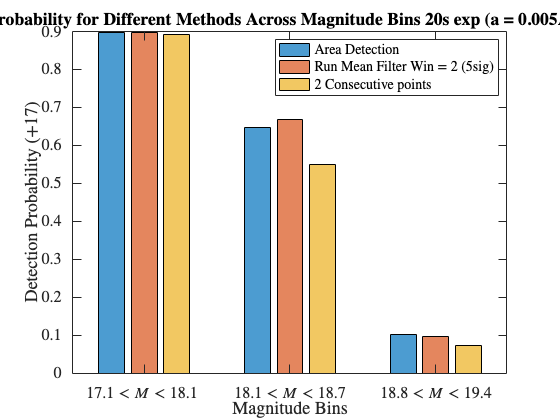



%%

% Sample data for detection probabilities
% Rows correspond to magnitude bins
% Columns correspond to methods
detection_probabilities = [
    DetectionsMB1, RMF_detections(1),pdetections1;   % Mag Bin 1
   DetectionsMB2, RMF_detections2(1),pdetections2;  % Mag Bin 2
     DetectionsMB3, RMF_detections3(1),pdetections3;  % Mag Bin 3
];

% Define the magnitude bins
mag_bins = {'$17.1 < M < 18.1$ ', '$18.1 < M < 18.7$', '$18.8 < M < 19.4$'};

% Define the methods
methods = {'Area Detection', 'Run Mean Filter Win = 2 (5sig)', '2 Consecutive points'};

% Create the bar plot
figure('color','white');
b = bar(detection_probabilities, 'FaceAlpha', 0.7);

% Add labels and title
xlabel('Magnitude Bins');
ylabel('Detection Probability (+16)');
title('Detection Probability for Different Methods Across Magnitude Bins 20s exp (a = 0.005AU ; R = R_E)');
set(gca, 'XTickLabel', mag_bins);

% Add a legend
legend(methods);

% Set transparency for each bar
for k = 1:length(b)
    b(k).FaceAlpha = 0.7; % Adjust alpha as needed
end

% Optionally, customize colors if needed
% colors = [0.2, 0.2, 0.5; 0.4, 0.6, 0.3; 0.7, 0.3, 0.2];
% for k = 1:length(b)
%     b(k).FaceColor = colors(k, :);
% end

% Display the plot
grid off;

%%



load('/Users/yarinms/Documents/Data/Mex19s3_16.mat')
load('/Users/yarinms/Documents/Data/Mex18s3_16.mat')
load('/Users/yarinms/Documents/Data/Mex17s3_16.mat')
%% histogram of control group;



% Sample data for demonstration
vec1 =tSD18; % Replace with your data

Unrecognized function or variable 'tSD18'.

vec2 = tSD19; % Replace with your data
vec3 = tSD195; % Replace with your data

% Calculate medians
med1 = median(vec1);
med2 = median(vec2);
med3 = median(vec3);

% Create histograms
figure('color','white');
hold on;

h1 = histogram(vec1, 'Normalization', 'pdf','DisplayStyle', 'stairs', 'LineWidth', 1.5);
h2 = histogram(vec2, 'Normalization', 'pdf','DisplayStyle', 'stairs', 'LineWidth', 1.5);
h3 = histogram(vec3, 'Normalization', 'pdf','DisplayStyle', 'stairs', 'LineWidth', 1.5);

% Set histogram properties
h1.EdgeColor = [0.6, 0.8, 1];
h2.EdgeColor = [1, 0.6, 0.6];
h3.EdgeColor = [0.7, 1, 0.7];

% Add labels
xlabel('Standard Deviation');
ylabel('Frequency');
legend(sprintf('18 < M < 18.5, Median = %.3f', med1), ...
       sprintf('18.5 < M < 19, Median = %.3f', med2), ...
       sprintf('19 < M < 19.5, Median = %.3f', med3));

title('Histograms of control group SD');

hold off;
